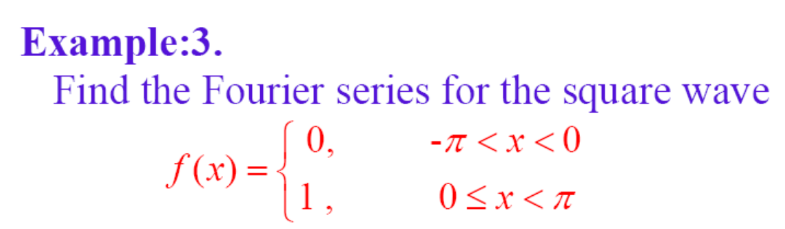

clear;clf;
syms x n;
assume(n, 'integer');
f1 = 0;f2 = 1;
a0 = vpa(simplify((1/pi)*(int(f1,x,-pi,0)+int(f2,x,0,pi))),3)

$$a0 = 1.0$$

an = vpa(simplify((1/pi)*int(f2*cos(n*x),x,0,pi)),3)

$$an = 0.0$$

bn = vpa(simplify((1/pi)*int(f2*sin(n*x),x,0,pi)),3)

$$bn = \frac{0.637\,{\sin\left(1.57\,n\right)}^{2}}{n}$$

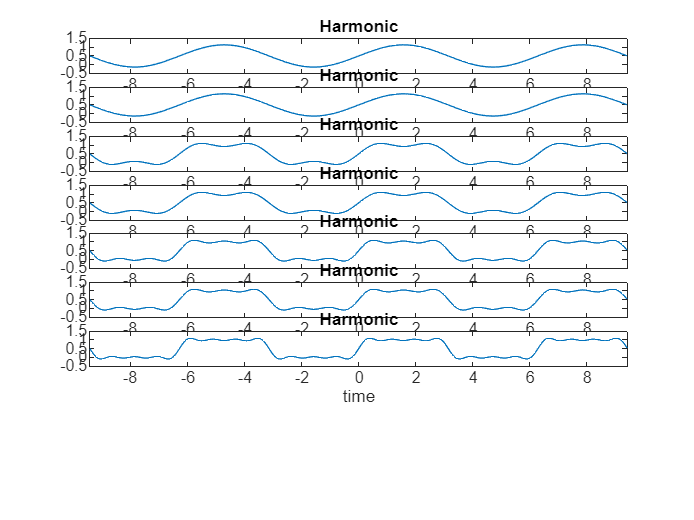

Current plot held


f0 = (an*cos(n*x))+(bn*sin(n*x));
harm = 7;
for i = 1:harm
     f(x) = a0/2 + symsum(f0,n,1,i);
     subplot(harm+2,1,i)
     fplot(f(x),[-3*pi 3*pi])
     title('Harmonic')
     xlabel('time')
     ylim([-0.5, 1.5]);
end
hold